# Computer exercise 1

## 1  Introduction to estimation of expected value, covariance function and spectral density

### 1.1 Estimation of expected value 

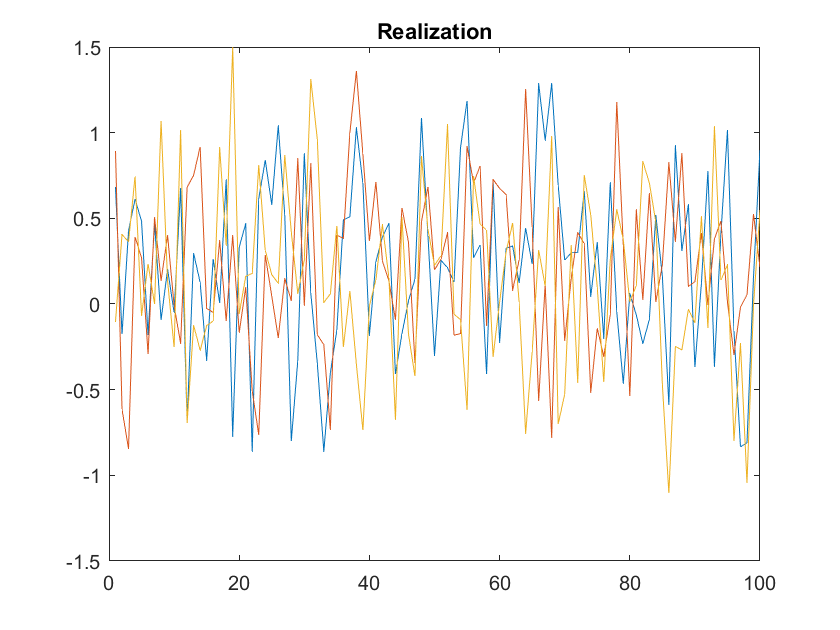

load data.mat;
figure(1)
plot([data1 data2 data3]);
title("Realization")

m=[mean(data1) mean(data2) mean(data3)];

**Q1**: Smilar mean, similar variance. Not really zero mean

% We calculate the confidence intervall
variance= 0.25;
n= length(data1);
d = [norminv(0.025) norminv(0.975)].*(sqrt(variance)./sqrt(n));
I = [m(1)+d; m(2)+d; m(3)+d]

I =     0.1232    0.3192
    0.1280    0.3240
    0.0550    0.2510


**Q2**: We find that none include 0 in the confidence intervall.

% Assuming same process we calculate the mean
mean_all= mean(m)

mean_all = 0.2001

**Q3**: Final mean: 0.2001

### 1.2 Estimation of covariance function

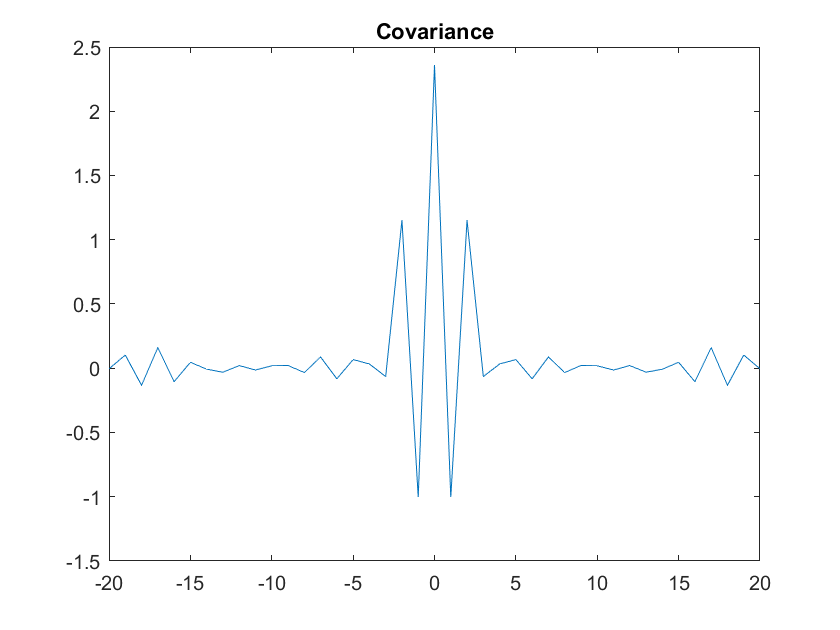

%Estimating covarience function
load data2.mat
[r,lags]=xcov(y,20,'biased');
plot(lags,r)
title("Covariance")

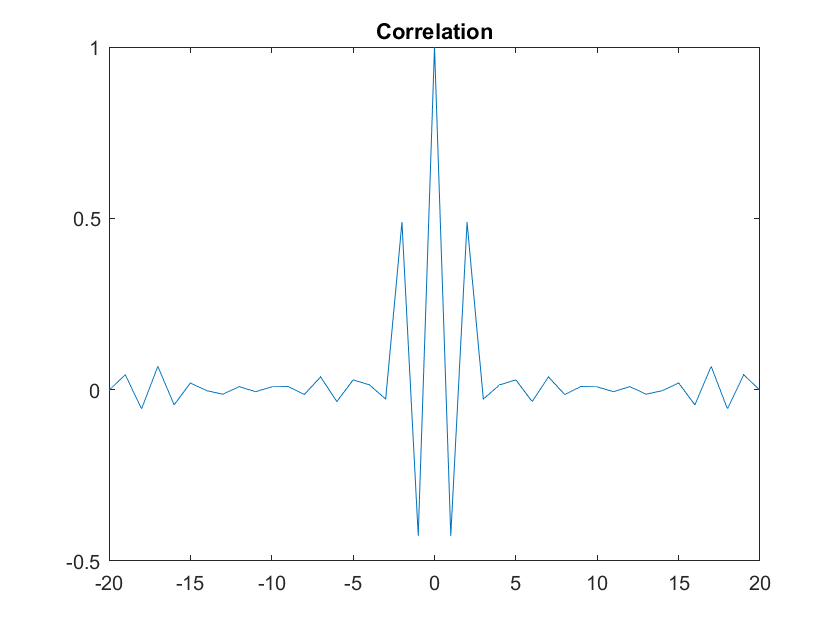

%Estimating correlation function
[rho,lags]=xcov(y,20,'coeff');
figure(3)
plot(lags,rho)
title("Correlation")

**Q4**: $\rho(\tau)= \frac{r(\tau)}{r(0)} $

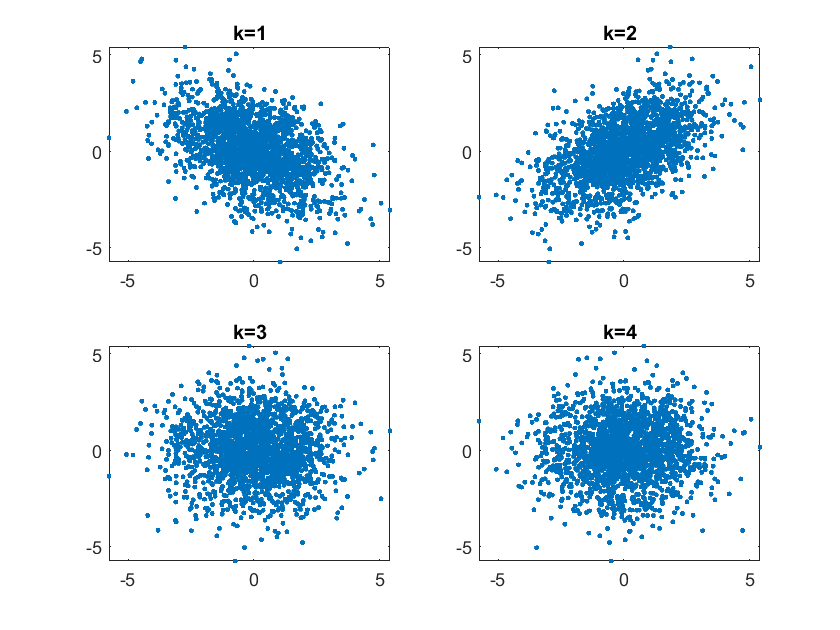

%ploting y(t) and y(t-k) for k=1,2,3,4
for k=1:4
    subplot(2,2, k);
    plot(y(1:end-k),y(k+1:end),'.');
    title("k=" + k)
end